clear all 
close all
clc

## constants

filter=0.0008; %This determines the amount of low frequencies that will be made zero, if it is increased the accurracy will be less and file size will also be less
R=500;

## load signal

load weatherEindhoven
y=weatherEindhoven;

## compute Fast Fourier Transform

figure
N=length(y);
M=N/R;
%M=N/100;
Y=fft(y,N);  %computes the Fourier Transform
PSD = Y.*conj(Y)/N; %This is the power spectrum used for finding the power of the frequencies

## how much power in each frequency

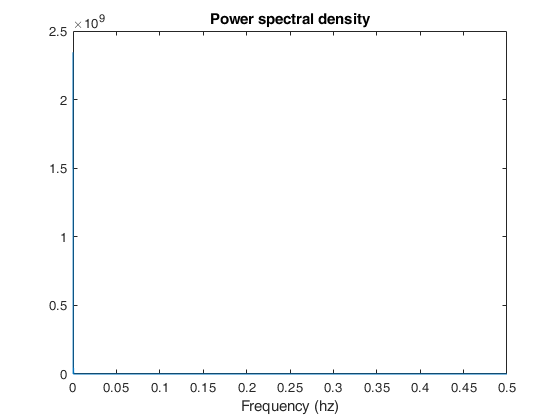

freq= 1/(N)*(0:N);
L=1:floor(N/2);
figure(1)
plot(freq(L),PSD(L))
xlabel('Frequency (hz)')
title('Power spectral density')         %In this part the frequencies are plotted with corresponding power

## use PSD to filter out low frequencies

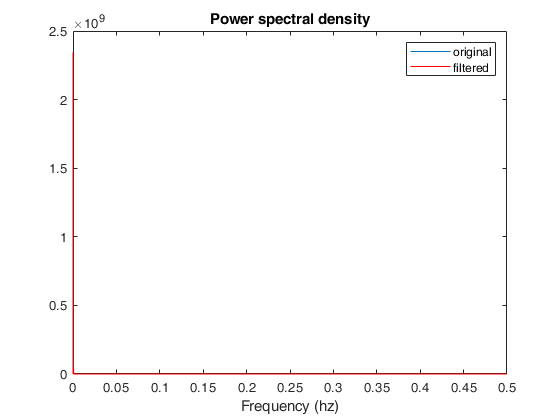

indices = PSD> filter*max(abs(Y(:)));   %find all indices with large power, found by looking at plot

PSD=PSD.*indices; %all other indices become zero
hold on
plot(freq(L),PSD(L),'r')    %this plot shows the result of setting low power frequencies to zero
legend('original','filtered')

## Zero all low frequency FFT values

 thresh = filter * max(abs(Y(:))); %this is the threshold, frequencies with higher energy are set to zero
 ind = abs(Y)>thresh;
 compressedFFTWeather_power= Y.*ind;
 compressedFFTWeather_power = compressedFFTWeather_power(1:M); %as in the normal version we only take the first M values
 
 save compressedFFTWeather_power compressedFFTWeather_power %save the compressed file so that it can be decompressed later
 count = N - sum(ind(:));
 percent= 100-count/N*100;      %this percentage shows how much of the FFT data(frequencies) is actually kept

## Inverse FFT to get original signal

 load compressedFFTWeather_Wouter

Error using load
Unable to read file 'compressedFFTWeather_Wouter'. No such file or directory.

 compressedFFTWeather        = [compressedFFTWeather_power zeros(1,N-2*M+1) transpose(compressedFFTWeather_power(end:-1:2)')];
 compressedWeather=ifft(compressedFFTWeather,'symmetric');

## Plot results

figure(2)
plot(compressedWeather(end-10000:end),'r')
 hold on
plot(weatherEindhoven(end-10000:end),'b')
legend('compressed', 'original')
title('Compressed and original signal')
ylabel('Temperature in Celsius')
xlabel('Time in minutes')

## Determine file size

s = dir('compressedFFTWeather_power.mat');         
filesize = s.bytes